# Variable Scaling Analyzer

Copyright 2023-2024 The MathWorks, Inc.

Scaling Simscape variables by their expected magnitude increases simulation robustness and performance. The techniques allows to provide a fine-tune scaling of variables in a Simscape model. 

openExample('simscapeelectrical/PMSMTractionDriveExample') 

It is best practice to have variable scaling enabled. This can be enabled or confirmed in the Model Settings:

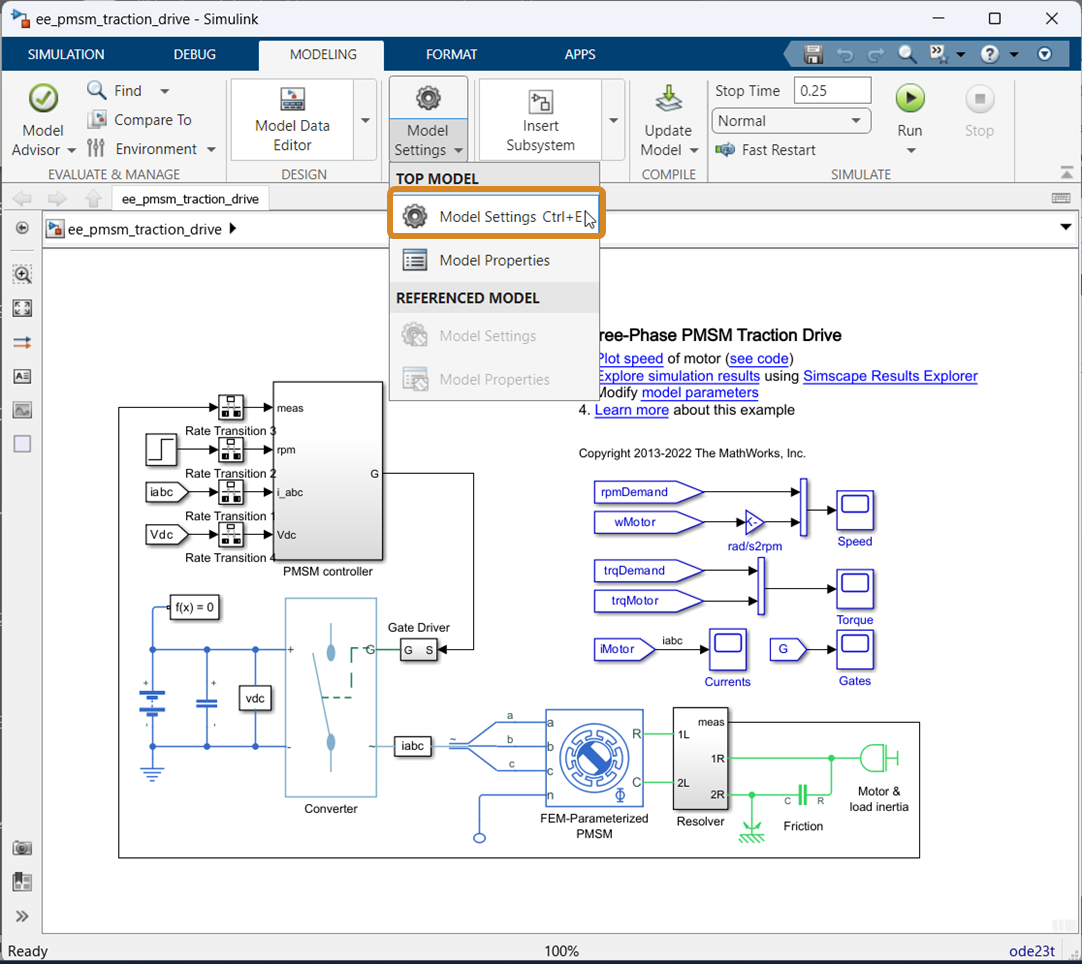

Under *Simscape* the item *Normalize using nominal values* should be checked:

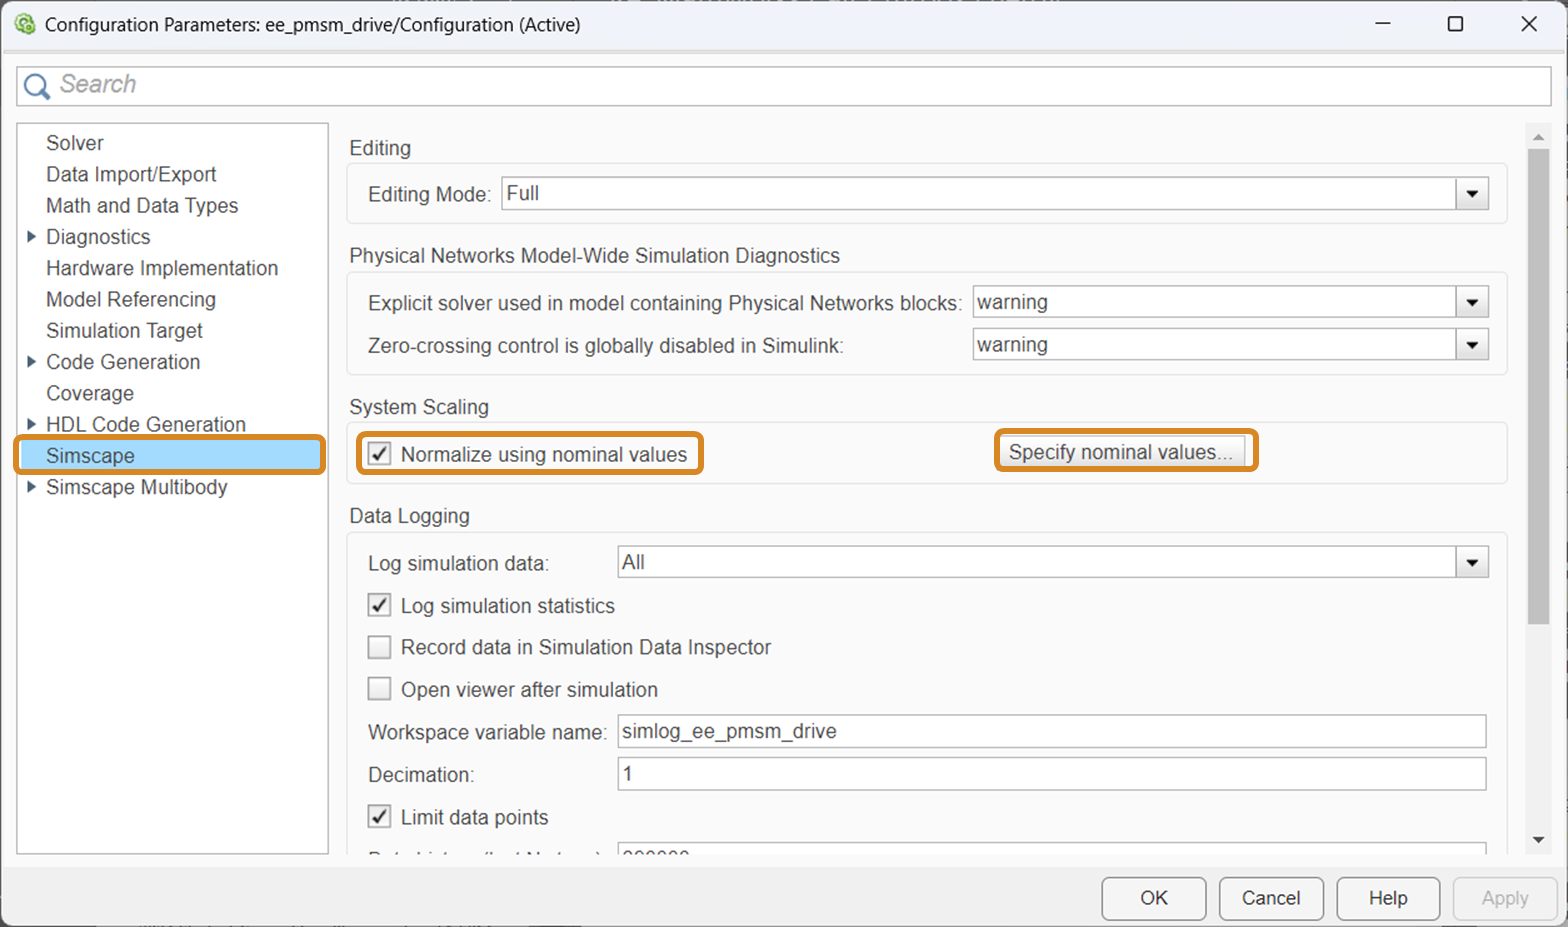

Clicking *Specify nominal values *opens the dialogue to change add and remove model-wide nominal values:

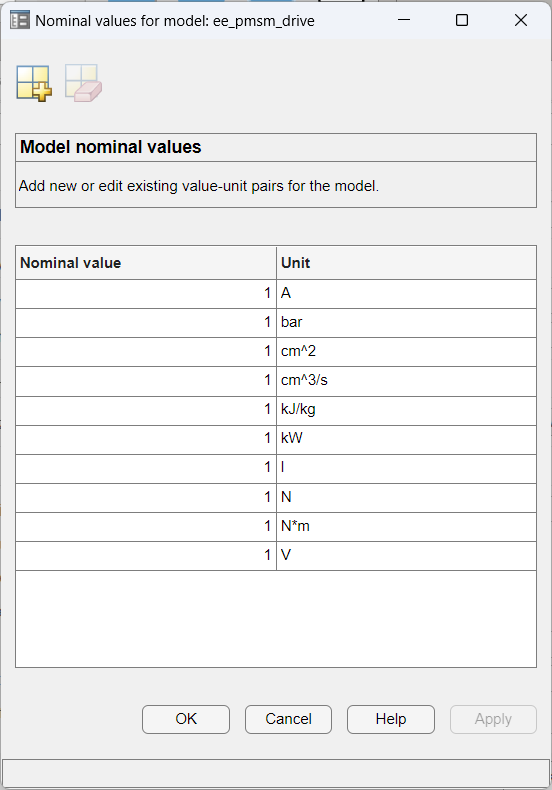

The nominal values are defined ar value-unit pairs. Variables of that unit will be scaled by the corresponding values. Edit a pair by selecting the field, remove and add pairs by choosing the corresponding items in the window:

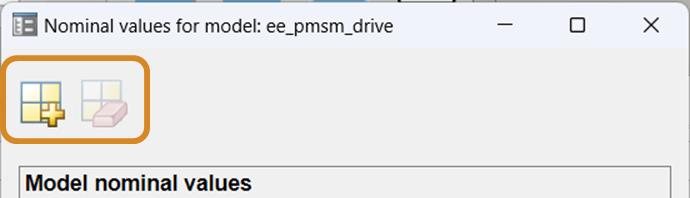

Some Simscape blocks provide the option of defining nominal values that will be specific for those block variables, for example:

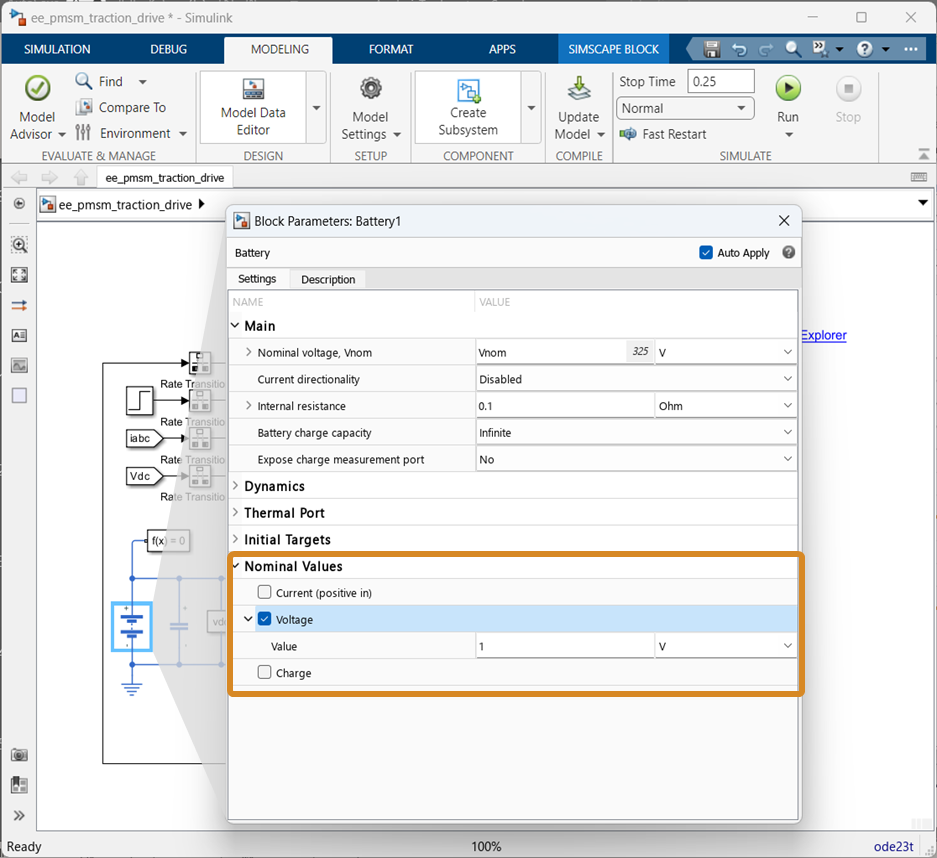

The nominal values can also be *derived*, in case the nominal value is not defined elsewhere. Read more in [System Scaling by Nominal Values](https://www.mathworks.com/help/releases/R2023a/simscape/ug/system-scaling-by-nominal-values.html?s_tid=doc_srchtitle#responsive_offcanvas). The scaling will effect the absolute tolerance (as set in the Solver settings) values for the attached variables. 

To identify and resolve potential issues from poor variable scaling, the Simscape Variable Scaling Analyzer. The app uses the simulation results with respect to the absolute tolerance values to visualize the effects of the variable scaling, provide statistical information and make recommendations for improved scaling. 

Open the Variable Scaling Analyzer and run an analysis:

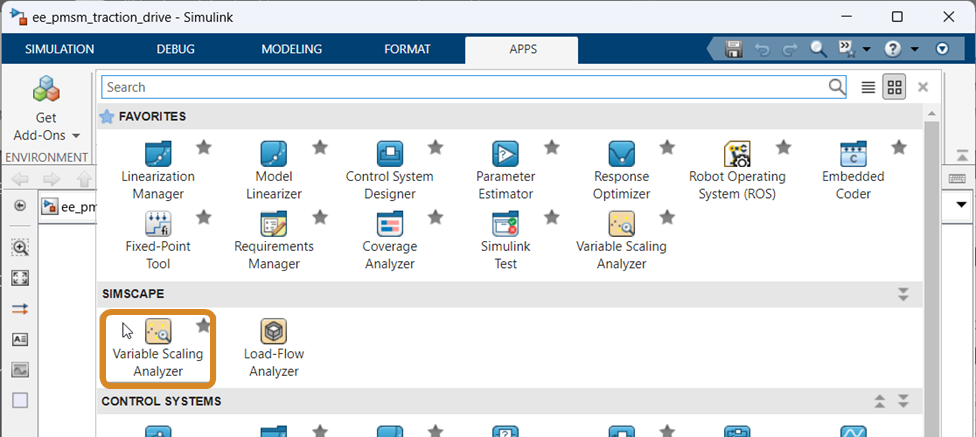

Deactivate the local solver in the Block Solver Configuration, because the variable scaling analysis works only for continuous variables. 

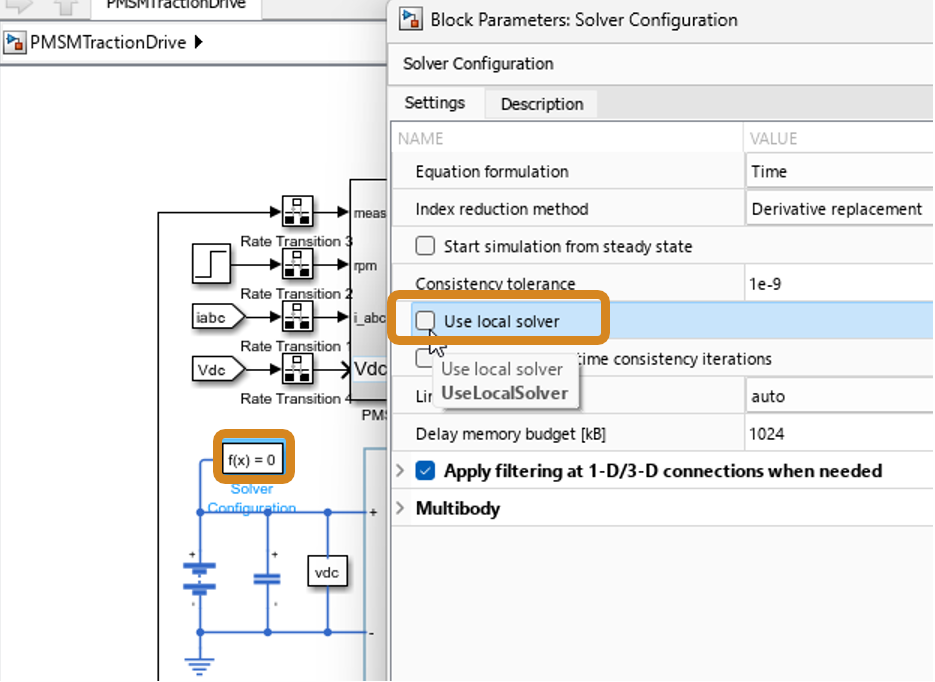

Run the simulation from the app, you might want to select a model to attach it to first, if multiple models are open:

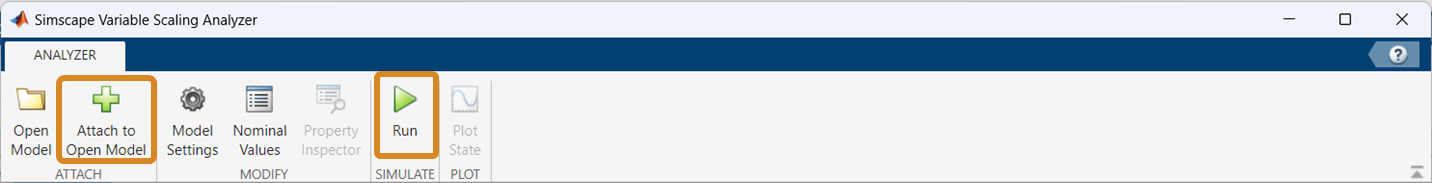

In the results the potentially problematic states will be highlighted in yellow in the *Raw Data* pane and suggestions will be provided in the *Messages* pane. Selecting a highlighted state and clicking *Plot State* will visualize the state with the corresponging tolerance band.

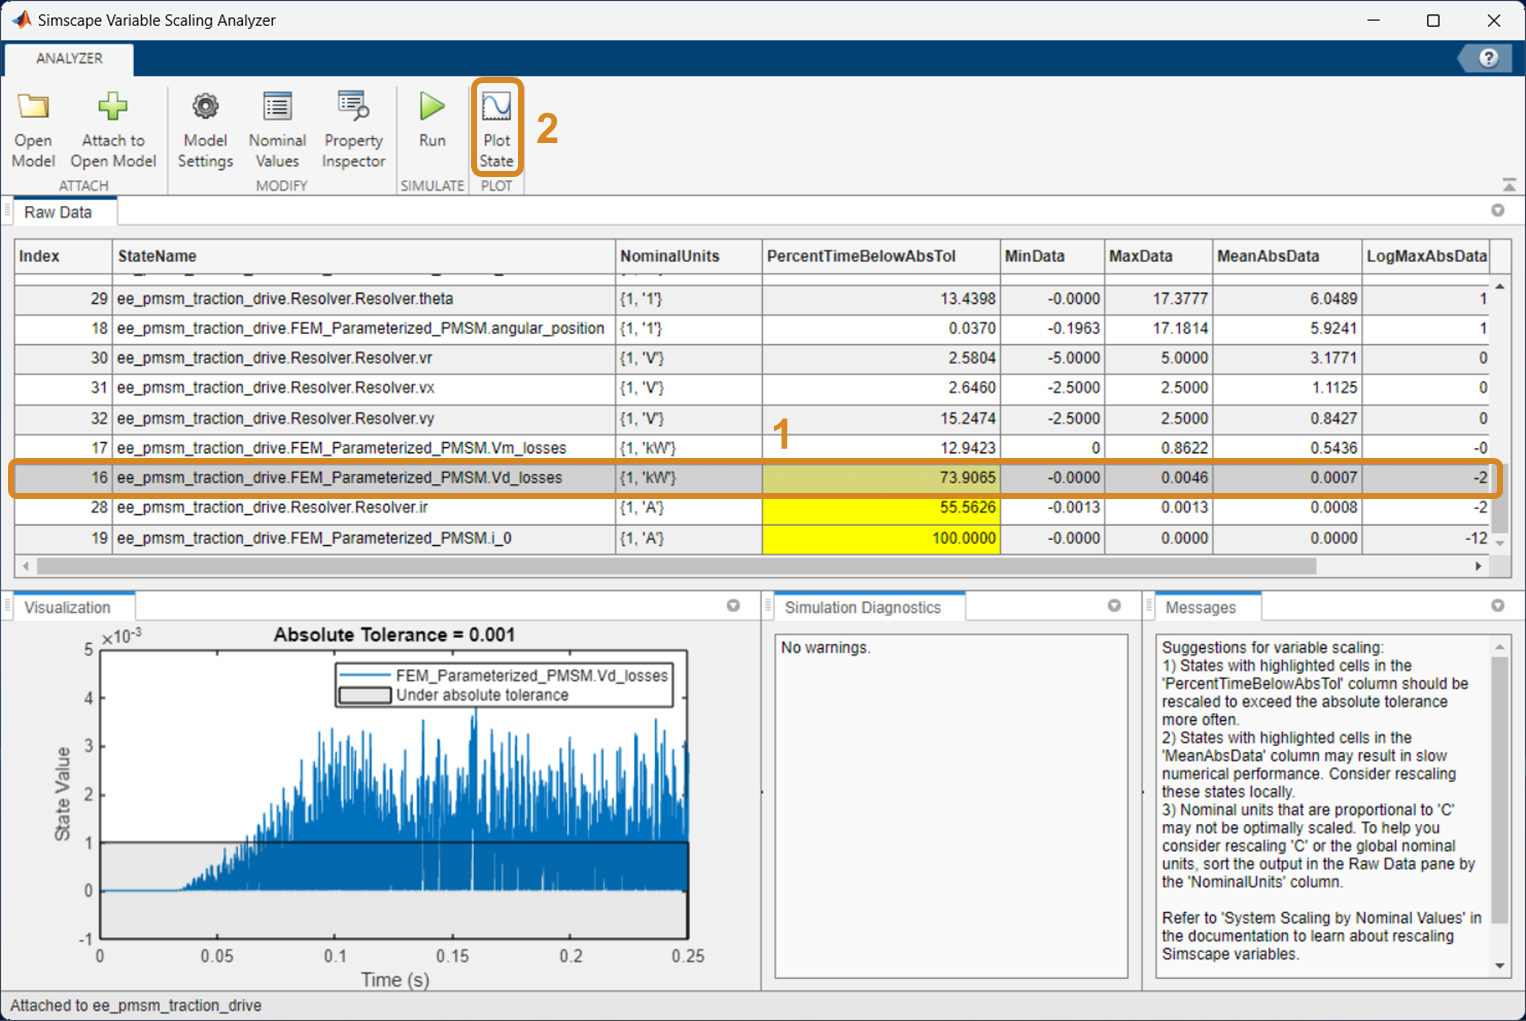

The report will highlight states which values are within the tolerance within a signifcant time. If this is not considered noise, these should be rescaled to be within the tolerance bound less often. This can improve the simulation performance. 

Additionally the app might highlight where values trend to be close to the absolute tolerance but not below it and states values which are orders of magnitude larger than other variables. 

Directly selecting Nominal Values to adapt the model-wide scaling and re-running the simulation from the app allows to check, how changes in scaling affect the result.